rng(0);
N = 20

N = 20

m = 50

m = 50

r = rand(N^2,1);
A = gallery('poisson',N);
[V,T] = lanczos(A,r,m)

V =     0.0712    0.0325   -0.1433    0.0271    0.0619    0.0299   -0.0160   -0.0071    0.0154    0.0092   -0.0126   -0.0478   -0.0395    0.0183    0.0692   -0.0399   -0.0039    0.0330   -0.0140   -0.0476    0.0147    0.0311    0.0217    0.0170   -0.0152    0.0128    0.0210   -0.0077   -0.0526   -0.0162   -0.0266    0.0147    0.0629    0.0174   -0.0556   -0.0315    0.0501   -0.0158   -0.0018    0.0284    0.0006   -0.0056   -0.0013   -0.0382   -0.0258    0.0261    0.0393    0.0061    0.0175   -0.0801
    0.0792    0.0696   -0.0064    0.0488   -0.0784   -0.0098    0.0168   -0.0382   -0.0475    0.0411    0.0810    0.0062   -0.0026    0.0228    0.0310   -0.0975    0.0083    0.0364    0.0073    0.0005   -0.0121   -0.0193    0.0002   -0.0357   -0.0660    0.0333    0.0085   -0.0074    0.0151    0.1122    0.0173   -0.0448   -0.0707   -0.0248    0.0490    0.0236    0.0293   -0.0451   -0.0212    0.0002   -0.0069   -0.0040    0.0200    0.0374    0.0347   -0.0112   -0.0511   -0.0694    0.0876    0

T =     1.1793    1.9795         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.9795    4.6166    1.7821         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

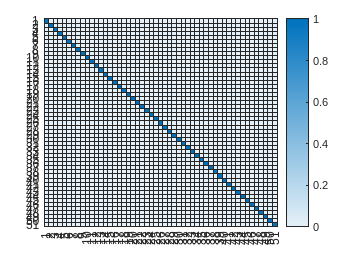

heatmap(V'*V)

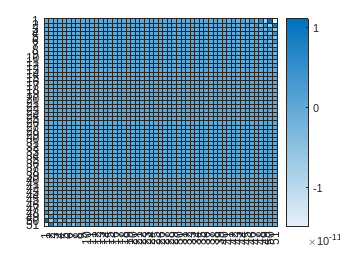

heatmap(V' * V - eye(m+1))

B = konv_diff(N,1e-10);

[V1,H1] = arnoldi(A,r,m);
[V2,H2] = arnoldi(B,r,m);

heatmap(V1'*V1)

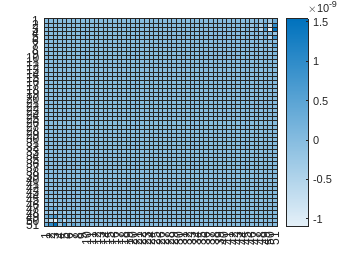

heatmap(V1'*V1 - eye(m+1))


heatmap(V2'*V2)

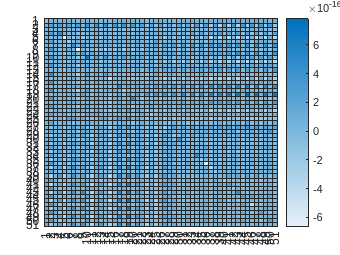

heatmap(V2'*V2 - eye(m+1))

[V, H] = arnoldi_RE(A, r, m);
heatmap(V'*V)

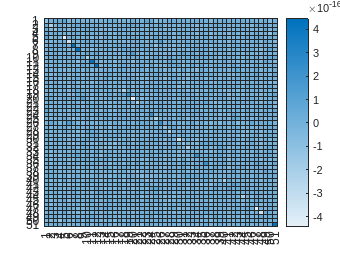

heatmap(V'*V - eye(m+1))

c = -1 + sqrt(5) * 1i;
c2 = 4i

c2 = 0.0000 + 4.0000i

C = A + sparse(c2 * eye(size(A)));
[V,T] = lanczos(A,r,m);
[Vc,Tc] = lanczos(C,r,m);
Vc

Vc =    0.0712 + 0.0000i   0.0078 + 0.0691i  -0.0706 + 0.0072i  -0.0086 - 0.0700i   0.0703 - 0.0085i   0.0088 + 0.0701i  -0.0702 + 0.0088i  -0.0088 - 0.0702i   0.0702 - 0.0088i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i  -0.0702 + 0.0089i  -0.0089 - 0.0702i   0.0702 - 0.0089i   0.0089 + 0.0702i
   0.0792 + 0.0000i   0.0167 + 0.0768i  -0.0

Tc

Tc = 1.0e+15 *

   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 0.

Vc' * Vc

ans =    1.0000 + 0.0000i  -0.0000 + 0.9707i  -0.9700 - 0.0080i   0.0070 - 0.9616i   0.9613 + 0.0090i  -0.0087 + 0.9592i  -0.9592 - 0.0093i   0.0092 - 0.9587i   0.9586 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i  -0.9585 - 0.0093i   0.0093 - 0.9585i   0.9585 + 0.0093i  -0.0093 + 0.9585i
  -0.0000 - 0.9707i   1.0000 + 0.0000i   0.

[Vc, Hc] = arnoldi(C, r, m);
Vc

Vc =    0.0712 + 0.0000i   0.0078 + 0.0691i  -0.0290 + 0.0282i  -0.0338 - 0.0386i   0.1333 + 0.0194i  -0.0292 + 0.1284i  -0.0114 - 0.0062i   0.0121 + 0.0040i   0.0527 + 0.0268i  -0.0150 + 0.0602i  -0.0192 + 0.0299i  -0.0246 - 0.0062i  -0.0004 + 0.0184i  -0.0215 + 0.0051i  -0.0200 + 0.0030i  -0.0067 - 0.0181i   0.0052 + 0.0059i  -0.0059 + 0.0081i  -0.0300 + 0.0081i  -0.0142 - 0.0319i   0.0223 - 0.0244i   0.0290 + 0.0191i  -0.0186 + 0.0417i  -0.0435 - 0.0160i   0.0102 - 0.0375i   0.0288 + 0.0172i  -0.0428 - 0.0074i   0.0133 - 0.0450i   0.0205 + 0.0102i  -0.0166 + 0.0109i   0.0040 - 0.0373i   0.0405 - 0.0025i   0.0251 + 0.0369i  -0.0296 + 0.0200i   0.0128 - 0.0083i   0.0081 + 0.0099i   0.0293 + 0.0258i  -0.0179 + 0.0339i  -0.0196 + 0.0244i  -0.0235 - 0.0155i   0.0158 + 0.0113i  -0.0136 + 0.0162i  -0.0113 + 0.0112i  -0.0090 - 0.0087i   0.0038 + 0.0225i  -0.0238 + 0.0074i  -0.0256 + 0.0026i  -0.0058 - 0.0276i   0.0161 + 0.0087i  -0.0050 + 0.0051i
   0.0792 + 0.0000i   0.0167 + 0.0768i  -0.0

Hc

Hc =    1.1793 - 4.0000i  -3.4074 - 1.1447i   0.2269 - 1.0008i  -1.9231 - 0.3334i  -0.1723 + 0.1882i  -0.2575 - 0.0122i  -0.1025 + 0.0337i  -0.0669 + 0.0233i  -0.0401 + 0.0083i  -0.0207 + 0.0143i  -0.0150 + 0.0022i  -0.0050 + 0.0069i  -0.0058 + 0.0005i  -0.0013 + 0.0032i  -0.0023 + 0.0001i  -0.0000 + 0.0015i  -0.0007 + 0.0000i   0.0002 + 0.0006i  -0.0001 + 0.0000i   0.0002 + 0.0002i   0.0000 - 0.0000i   0.0001 + 0.0001i   0.0001 - 0.0000i   0.0001 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i
   8.2413 + 0.0000i   2.4888 - 0.6923i   1.1